Load the data.

(given script)

loaddata

../Data/ACTOBS_S01_20161109_1108.mat
../Data/ACTOBS_S02_20161207-1002.mat
../Data/ACTOBS_S03_20161122-1529.mat
../Data/ACTOBS_S04_20161125-1211.mat
../Data/ACTOBS_S05_20161118_1339.mat
../Data/ACTOBS_S06_20161125-1033.mat
../Data/ACTOBS_S07_20161202-1521.mat
../Data/ACTOBS_S08_20161207-1434.mat
../Data/ACTOBS_S09_20161209-0958.mat
../Data/ACTOBS_S10_20161215-1615.mat
../Data/ACTOBS_S11_20161216-1131.mat
../Data/ACTOBS_S12_20161222-1036.mat
../Data/ACTOBS_S13_20161222-1406.mat
../Data/ACTOBS_S14_20170106-1517.mat
../Data/ACTOBS_S15_20170203-1237.mat
    flipped responses for block 1!
../Data/ACTOBS_S16_20170110-1509.mat
../Data/ACTOBS_S17_20170117-1048.mat
../Data/ACTOBS_S18_20170127-1459.mat
../Data/ACTOBS_S20_20170202-1235.mat
../Data/ACTOBS_S21_20170208-1404.mat
../Data/ACTOBS_S22_20170209-1228.mat
../Data/ACTOBS_S23_20170210-0956.mat
../Data/ACTOBS_S24_20170215-1430.mat
../Data/ACTOBS_S25_20170216-1146.mat
../Data/ACTOBS_S26_20170306-1121.mat
../Data/ACTOBS_S27_20170228-1126.mat
../

Inital fits ('nrep' number of fits) of the actual data to obtain an estimate of the two variables of interest, the probability of reversal (prev) and the choice probability (beta), that will serve fixed refence values to the next analyses.

nrep = 10;

clear prev_fit beta_fit % to prevent any dimension error when using MATLAB LiveScript environment 
[prev_fit, beta_fit] = initialfit(nrep, nsubj, dat, subjlist);

prev_fix = mean(prev_fit(:)) % same fixed value across the tasks

prev_fix = 0.2087

beta_fix = mean(beta_fit(:))

beta_fix = 1.2439

Using a (given) function "sim_model_softmax", dataset are simulated using the fixed parameters (as the parameters are the same across the 2 tasks, we end up with 2*nsim simulated datasets).

nsim              = 5000;         % number of simulations
nsubjsubset       = [12 24 48 96] % subset(s) of participants (w/out consideration for condition, 96 = all)

nsubjsubset =     12    24    48    96



% preallocation, to save data across the subsets
prev_recov_subjave = zeros(2*nsim,length(nsubjsubset));
beta_recov_subjave = zeros(2*nsim,length(nsubjsubset));
    
prev_diff_subjave = zeros(2*nsim,length(nsubjsubset));
beta_diff_subjave = zeros(2*nsim,length(nsubjsubset));

meansd_prev_diff_subjave = zeros(length(nsubjsubset),2);
meansd_beta_diff_subjave = zeros(length(nsubjsubset),2);

mean_corr_prev_beta = zeros(length(nsubjsubset),1);
shared_var          = zeros(length(nsubjsubset),1);


for isubjsubset = nsubjsubset % for each subset of subjects

    prev_recov = zeros(isubjsubset,2,nsim); % to save data across subjects
    beta_recov = zeros(isubjsubset,2,nsim);
         
    isubjsubset % to display the current subset running in MATLAB LiveScript environment 
    seq_isubjsubsest = randperm(nsubj,isubjsubset) % to avoid selecting deterministically the same subjects across subsets
    for isubj = seq_isubjsubsest
    % given script -->
        for itask = 1:2
            
            % filter trials of interest
            ifilt = dat.subj == subjlist(isubj) & dat.task == itask;
            
            % simulate model
            cfg_sim        = [];
            cfg_sim.nsim   = nsim;
            cfg_sim.seqllr = dat.evid(ifilt);
            cfg_sim.seqind = dat.sind(ifilt);
            cfg_sim.prev   = prev_fix;
            cfg_sim.beta   = beta_fix;
            cfg_sim.brep   = 0; % force no repetition bias
            cfg_sim.epsi   = 0; % force no lapses
            
            out_sim        = sim_model_softmax(cfg_sim);
        

        Then each datasets is fit using the (given) function "fit_model_softmax".

            % fit simulated decisions
            for isim = 1:nsim
                cfg_fit        = [];
                cfg_fit.seqllr = out_sim.cfg.seqllr;
                cfg_fit.seqind = out_sim.cfg.seqind;
                cfg_fit.raft   = out_sim.raft(:,isim);
                cfg_fit.rbef   = out_sim.rbef(:,isim);
                cfg_fit.brep   = out_sim.cfg.brep; % force no repetition bias
                cfg_fit.epsi   = out_sim.cfg.epsi; % force no lapses
                    
                out_recov = fit_model_softmax(cfg_fit);
    % <-- given script             

        Estimated value of prev and beta from each simulation are stored and their average value is computed.

                % store model parameters
                revindexsubj = find(seq_isubjsubsest==isubj); % isubj goes over the index limit due to the 
                                                              % use of subsets --> reverse indexing
                prev_recov(revindexsubj,itask,isim) = out_recov.prev;
                beta_recov(revindexsubj,itask,isim) = out_recov.beta;
            end    
        end
    end

        Variables to plot histograms & histograms of the recovered parameters (if figures wanted, uncomment;  CAUTION: variables stored across subsets needed for final saving).

    prev_recov_cattask = squeeze(cat(3,prev_recov(:,1,:),prev_recov(:,2,:)))'; % concatenation of the data for the ...
    beta_recov_cattask = squeeze(cat(3,beta_recov(:,1,:),beta_recov(:,2,:)))'; % two tasks into one array (as if one task)
                                                                               % transposed matrix for dimension reason
    revindexsubset = find(nsubjsubset==isubjsubset); 
    prev_recov_subjave(:,revindexsubset) = mean(prev_recov_cattask,2);
    beta_recov_subjave(:,revindexsubset) = mean(beta_recov_cattask,2);
    
%     % figure to be played in MATLAB LiveScript environment, but not saved.
%     figure; 
%     hold on
%     title(["Probability of reversal (from n = ",num2str(isubjsubset)," subjects)"]);
%     hist(prev_recov_subjave(:,revindexsubset));
%     hold off
%     
%     figure;
%     hold on
%     title(["Choice probability (from n = ",num2str(isubjsubset)," subjects)"]);
%     hist(beta_recov_subjave(:,revindexsubset));
%     hold off
  

       Variables to plot histograms & histograms of the difference between the recovered-fixed parameters (if figures wanted, uncomment; CAUTION: variables stored across subsets needed for final saving & final plots).

    
    prev_diff = prev_recov - prev_fix;
    beta_diff = beta_recov - beta_fix;
     
    prev_diff_cattask = squeeze(cat(3, prev_diff(:, 1, :), prev_diff(:,2,:)))'; % concatenation of the data for the ...
    beta_diff_cattask = squeeze(cat(3, beta_diff(:, 1, :), beta_diff(:,2,:)))'; % two tasks into one array (as if one task)
                                                                                % transposed matrix for dimension reason
    
    prev_diff_subjave(:,revindexsubset) = mean(prev_diff_cattask, 2);
    beta_diff_subjave(:,revindexsubset) = mean(beta_diff_cattask, 2);
       
%     figure;
%     hold on
%     title(["Difference recovered-fixed probability of reversal (from n = ",num2str(isubjsubset)," subjects)"]);
%     hist(prev_diff_subjave(:,revindexsubset));
%     hold off
%     
%     figure;
%     hold on
%     title(["Difference recovered-fixed choice probability (from n = ",num2str(isubjsubset)," subjects)"]);
%     hist(beta_diff_subjave(:,revindexsubset));
%     hold off

       Mean & variance of the distribution of recovered parameters across simulations for each subset of participants.

    meansd_prev_diff_subjave(revindexsubset,1) = mean(prev_diff_subjave(:,revindexsubset));
    meansd_prev_diff_subjave(revindexsubset,2) = std(prev_diff_subjave(:,revindexsubset));
    
    meansd_beta_diff_subjave(revindexsubset,1) = mean(beta_diff_subjave(:,revindexsubset));
    meansd_beta_diff_subjave(revindexsubset,2) = std(beta_diff_subjave(:,revindexsubset));

        Correlation between the two parameters between subject is computed for each simulation.  

isubjsubset = 12

seq_isubjsubsest =     61    24    72    53    67    92    40    37    58    41     9    70


mean_corr_prev_beta =     0.3543
         0
         0
         0


isubjsubset = 24

seq_isubjsubsest =     50    93    25    59    74    15    91    32    69    36    16    79    44    20    60    80    30    49    38    65    54    39    46     2


mean_corr_prev_beta =     0.3543
    0.3532
         0
         0


isubjsubset = 48

seq_isubjsubsest =     83    40     1     5    72    22     2    53    30    55    20    65    41    19    35    90    42    60    81    51    89    68    11    54    67    38    62    49    75    18    87    77    44    32    13    45    15    12    34    94     9    39     7    78    73    74    91    88


mean_corr_prev_beta =     0.3543
    0.3532
    0.3583
         0


isubjsubset = 96

seq_isubjsubsest =     55    36    91    39     2    43    61    48    75    96    15    57    30    92    73    67    50    31    87     1    47    14    71    74    85    12    42    26     4    29    70    80     6    95    38    60     5    94    54    37    64    27    51    19    49    56    13    25    81    72


mean_corr_prev_beta =     0.3543
    0.3532
    0.3583
    0.3566


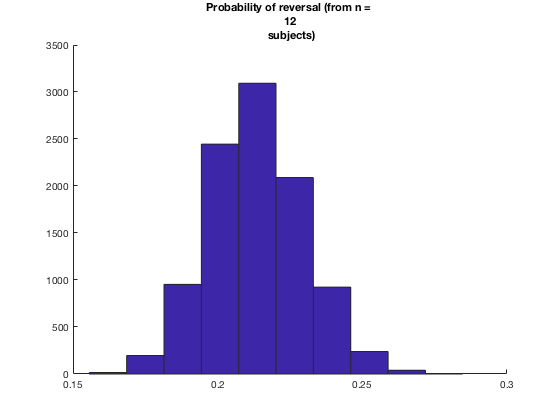

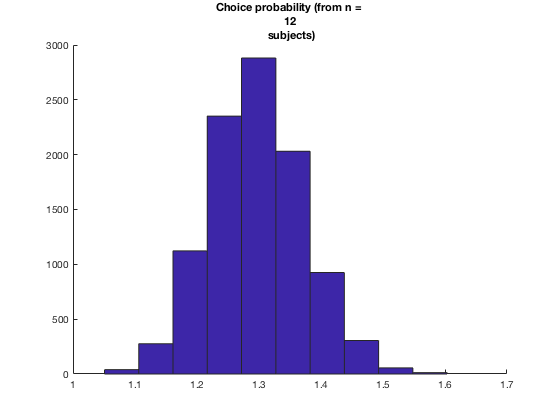

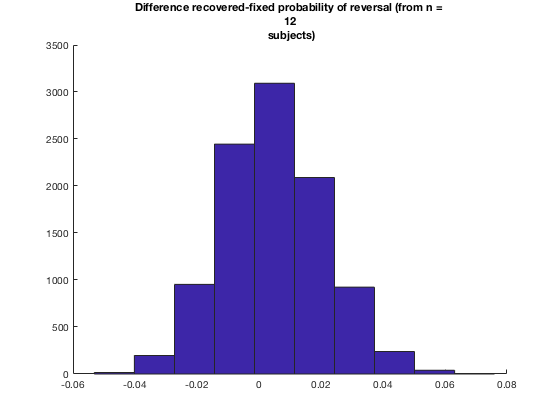

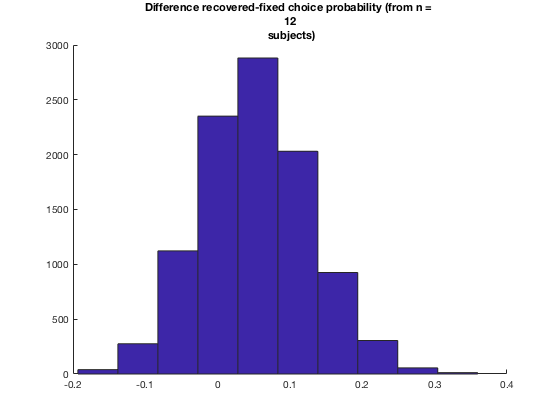

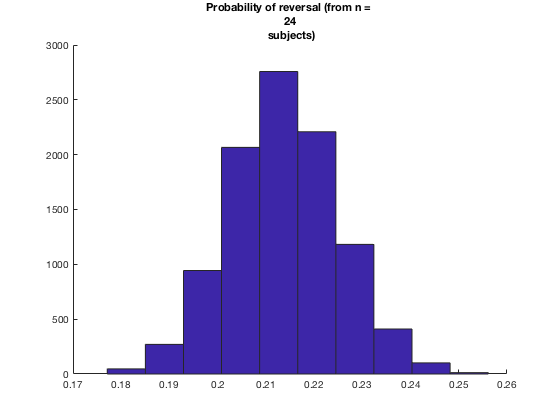

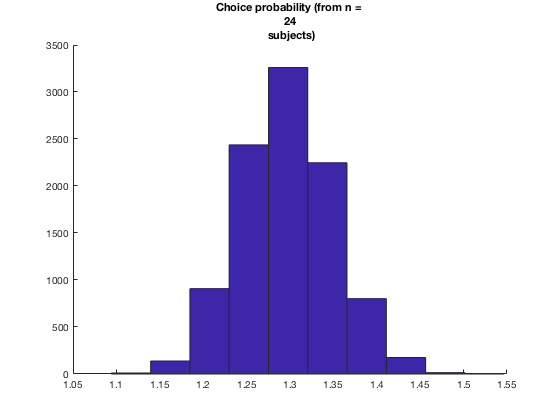

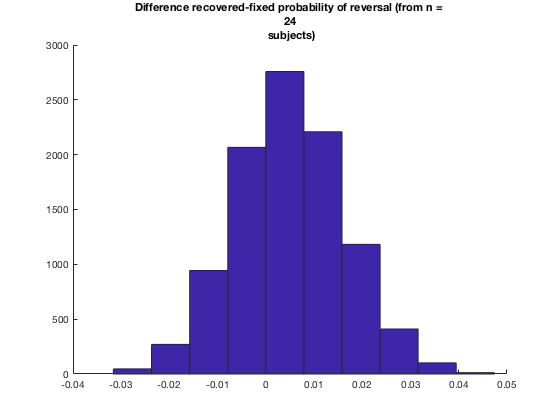

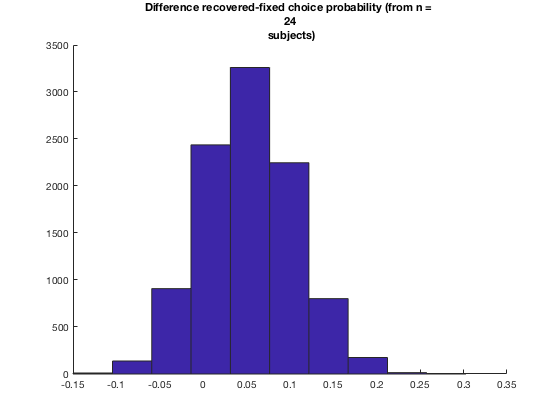

    corr_prev_beta = zeros(2*nsim,1);
    for isim = 1:2*nsim
        corr_prev_beta(isim) = corr(prev_recov_cattask(isim,:)', beta_recov_cattask(isim,:)'); % transposed to use function 'corr'
    end
    
    mean_corr_prev_beta(revindexsubset) = mean(corr_prev_beta)
    shared_var(revindexsubset)          = mean_corr_prev_beta(revindexsubset).^2;
    
end

Saving data of interest

dout = '../Out/' % folder for produced data

dout = '../Out/'


str_nsubjsubset = ''; % to nicely convert nsubjsubset into a string, e.g., "12-24-48-96"
for isubjsubset = nsubjsubset
    str_nsubjsubset = [str_nsubjsubset, num2str(isubjsubset),'-'];
end
str_nsubjsubset = str_nsubjsubset(1:end-1) % to delete the last useless '-'

str_nsubjsubset = '12-24-48-96'

    
formatSpec_file = '%s%s_2x%dsim_%ssubj%s';

name_file = sprintf(formatSpec_file, dout, 'recov', nsim, str_nsubjsubset, '.mat');
save(name_file) % to save the whole workspace

% To save only the variables needed for plotting:
% name_file = sprintf(formatSpec_file, dout, 'prev_recov', nsim, str_nsubjsubset, '.mat');
% save(name_file, 'nsim', 'nsubjsubset', 'prev_fix', 'prev_recov_subjave', 'prev_diff_subjave',    ...
%                 'meansd_prev_diff_subjave', 'mean_corr_prev_beta', 'shared_var')
% 
% name_file = sprintf(formatSpec_file, dout, 'beta_recov', nsim, str_nsubjsubset, '.mat');
% save(name_file, 'nsim', 'nsubjsubset', 'beta_fix', 'beta_recov_subjave', 'beta_diff_subjave',    ...
%                 'meansd_beta_diff_subjave', 'mean_corr_prev_beta', 'shared_var')

Histograms of the paramterer according the number of subject they were estimated from (n = 12, 24, 48 or 96).

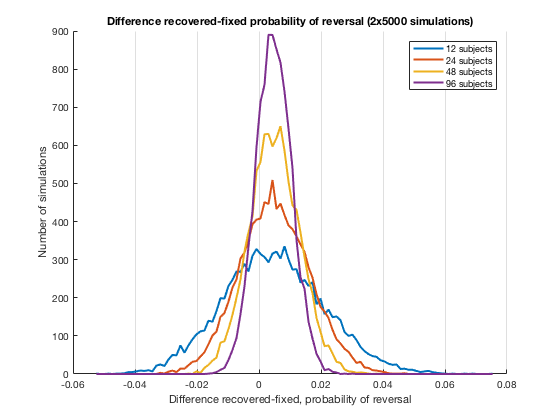

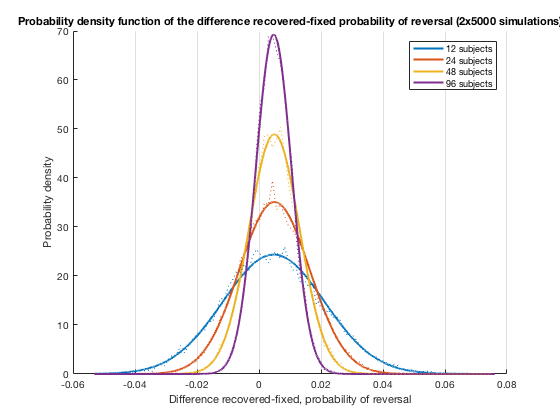

nbins = 100; % can be manually changed to the 'apparent noise' on the raw curves
            
finalplots_variance(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, ...
                          nbins, prev_diff_subjave, 'probability of reversal', 'prev')

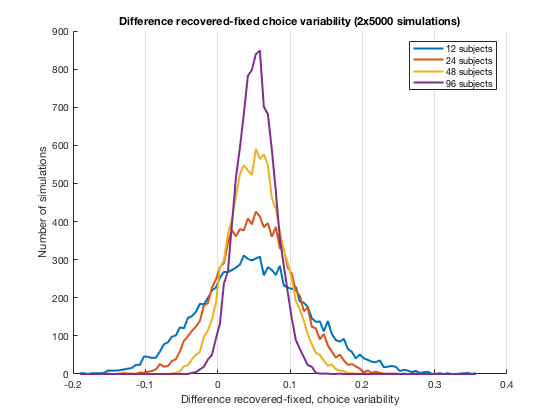

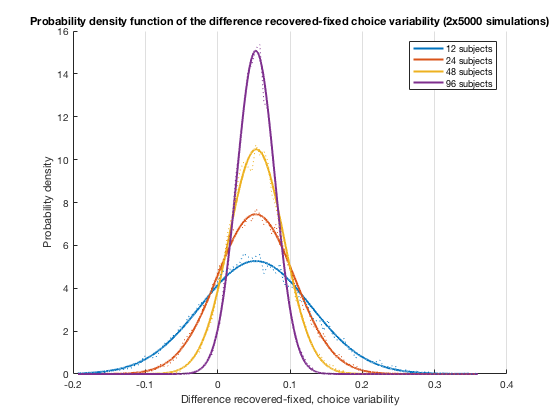


finalplots_variance(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, ...
                          nbins, beta_diff_subjave, 'choice variability', 'beta')

"Homemade R-style" scatterplots displaying the mean and the variance for each subset, for each parameter.

f_formatSpec_title = 'Mean %s (2x%d simulations)';
finalplots_hmscatter(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, f_formatSpec_title, ...
                           meansd_prev_diff_subjave(:,1), 'probability of reversal', 'mean_prev', 'Probability of reversal')

finalplots_hmscatter(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, f_formatSpec_title, ...
                           meansd_beta_diff_subjave(:,1), 'choice variability', 'mean_beta', 'Choice variability')
                          

"Homemade R-style" scatterplots displaying the correlation coeffcient or the shared variance between prev and beta for each subset.

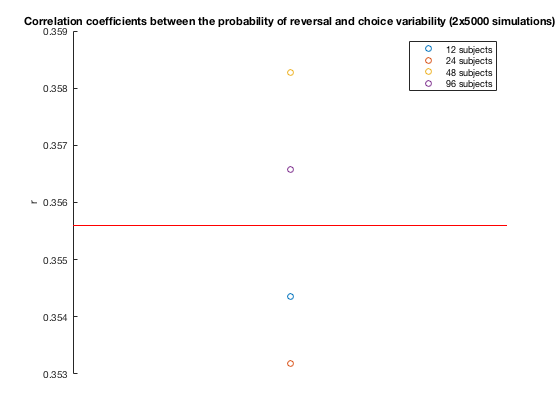

f_formatSpec_title = '%s between the probability of reversal and choice variability (2x%d simulations)';
finalplots_hmscatter(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, f_formatSpec_title, ...
                           mean_corr_prev_beta, 'Correlation coefficients', 'corr', 'r')

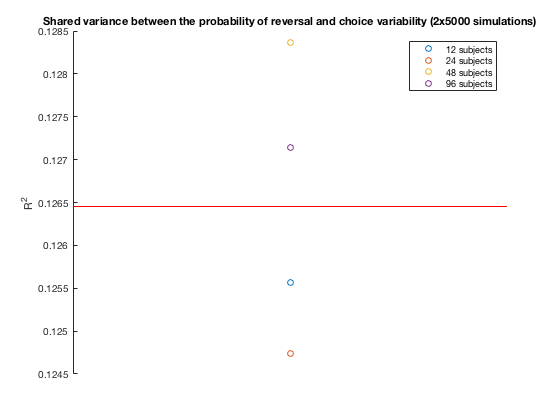


finalplots_hmscatter(dout, nsubjsubset, nsim, str_nsubjsubset, formatSpec_file, f_formatSpec_title,...
                           shared_var, 'Shared variance', 'sharedvar', 'R^2')